## Extract Service Resources using Map Reduce

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


## Actual Script below

### Create Datastore for Metrics

Read in .csv and create a datastore that can be used with mapreduce.

[ms_metrics_header, ms_metrics_formats, ~] = constants();
[~, ms_metrics_location, ms_metrics_header_lines, ~, ~, ~] = config();
metrics_ds = tabularTextDatastore(ms_metrics_location, "NumHeaderLines", ms_metrics_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", ms_metrics_header, ...
    "SelectedFormats", ms_metrics_formats, ...
    "SelectedVariableNames", ms_metrics_header);

clear ms_metrics_header;
clear ms_metrics_formats;
clear ms_metrics_location;
clear ms_metrics_header_lines;
clear ms_metrics_selected_formats;
prev_metrics_ds = copy(metrics_ds);
reset(prev_metrics_ds);
prev_metrics_ds.ReadSize = 10;
read(prev_metrics_ds)
clear prev_metrics_ds;

### Filter MsMetrics using Map Reduce

For the services we care about and within the timelimit we want.

[~, ~, ~, ms_metrics_max_timestamp, ~, ~] = config();

% Wrap mapFun to pass involved_ms
mapFunc = @(a, b, c)metrics_mapper(a, b, c, ms_metrics_max_timestamp);
reduceFunc = @(a, b, c)metrics_reducer(a, b, c);

ans = 10×6 table
    timestamp      ms_name          ms_instance_id          node_id        cpu_utilization    memory_utilization
    _________    ____________    ____________________    ______________    _______________    __________________

      300000     {'MS_68185'}    {'MS_68185_POD_91' }    {'NODE_20236'}        0.17238             0.66236      
      420000     {'MS_25215'}    {'MS_25215_POD_372'}    {'NODE_36528'}       0.085708             0.43286      
      720000     {'MS_31285'}    {'MS_31285_POD_916'}    {'NODE_23966'}        0.44523             0.57209      
      780000     {'MS_42019'}    {'MS_42019_POD_38' }    {'NODE_34880'}       0.091057             0.52934      
      900000     {'MS_9482' }    {'MS_9482_POD_332' }    {'NODE_45529'}        0.17766             0

fprintf("Inspecting metrics from 0-%i minutes", ms_metrics_max_timestamp / 60000);
tic
filtered_metrics_ds = mapreduce(metrics_ds, mapFunc, reduceFunc, 'OutputFolder', './results', 'Display', 'off');
toc

### Export to CSV

[~, ~, ~, ~, ~, metrics_output_file] = config();
entries = readall(filtered_metrics_ds);
flatter = vertcat(entries{:,2});

Inspecting metrics from 0-720 minutes

filtered_metrics = sortrows(vertcat(flatter{:,1}), "ms_name", "ascend");

t_export = filtered_metrics(:,["ms_name", "cpu_mean", "cpu_variance", "memory_mean", "memory_variance"]);

Elapsed time is 133.273729 seconds.


t_export.ms_name = k8s_conformous(t_export.ms_name);

fprintf("Writing export to file '%s'", metrics_output_file);
writetable(t_export, metrics_output_file, "Delimiter", "\t");

clear export;
clear entries;
clear flatter;
clear mapFunc;
clear reduceFunc;
clear metrics_output_file;

Writing export to file '../metrics_stats_normalized.csv'

clear ms_metrics_max_timestamp;

histogram(t_export.cpu_mean, 100);
title("Mean CPU Utilization distribution of all services");
ylabel("Count of entries");
xlabel("Normalized CPU");
fprintf("Mean CPU=%f", mean(t_export.cpu_mean));
histogram(t_export.cpu_variance, 100);
title("CPU Utilization variance of all services");
ylabel("Count of entries");
xlabel("Variance of normalized CPU ");

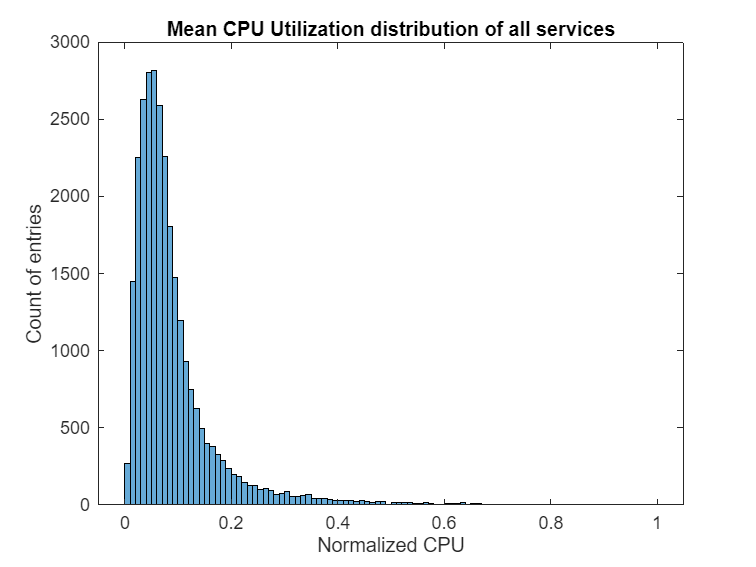

histogram(t_export.memory_mean, 100);
title("Mean MEMORY Utilization distribution of all services");
ylabel("Count of entries");

xlabel("Normalized MEMORY");

Mean CPU=0.090728

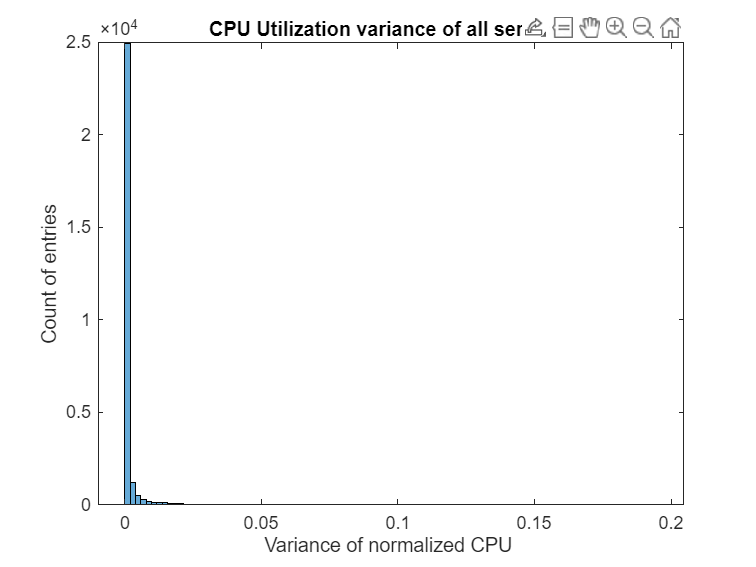

fprintf("Mean MEMORY=%f", mean(t_export.memory_mean));
histogram(t_export.memory_variance, 100);
title("MEMORY Utilization variance of all services");
ylabel("Count of entries");

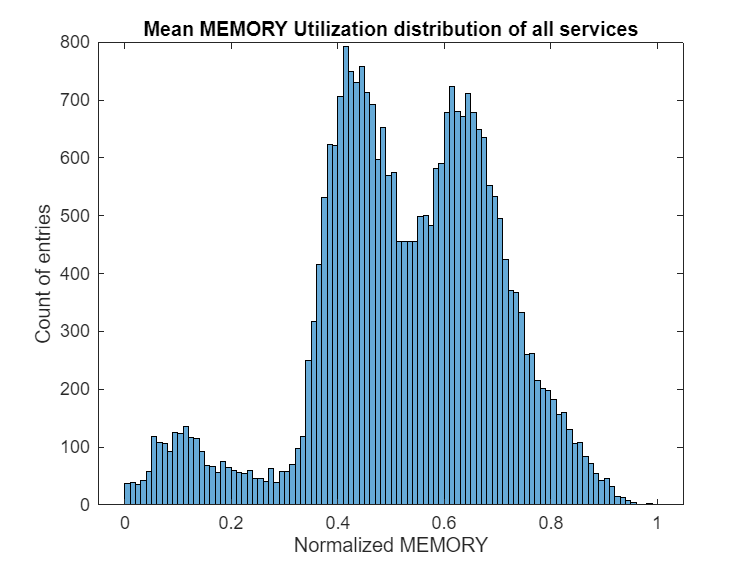

Mean MEMORY=0.529809

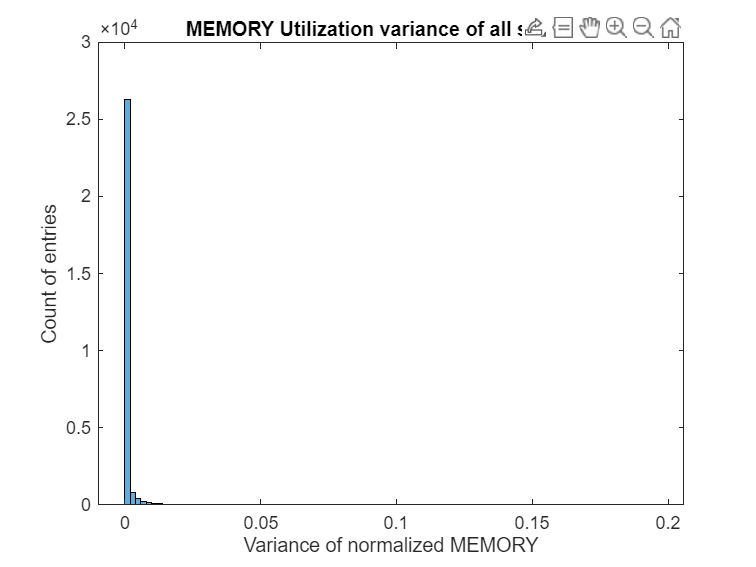

xlabel("Variance of normalized MEMORY");

### De-Normalize

The metric input data has been normalized with the min-max formular.

Sadly we do not know the MIN and MAX values that have been used, so we will need to find the values through experimentation.

Node Resource Utilization Means >>>> CPU: 0.2006 | MEMORY: 0.2708

Maybe we read in the services we are actually using within the trace data, where we know how many servers we aimed for

Then we can define our server sizes and reverse engineer the MIN and MAX params? :o

Actually calculate in workmodel-generator, as we can then use ENV vars as parameters (which could come from cloudlab parameterized profile)